# **Digital Communications TTT4130 - Matlab Lab Sessions**

**Lab Responsible**: Johan Suarez (johan.suarez@ntnu.no)

`Prerequisites`

Up-to-date installation of `MATLAB `and `SIMULINK `including `Communications Toolbox. (NTNU students receive Campus license)`

`Instructions`

**All lab sessions are group projects. Groups will be assigned randomly and consist of 2-3 people.** 

This is a Matlab live script. The script will guide through the lab session with coding tasks accompanied by explanations and comments.

**Please download and install MATLAB/Simulink and include the Communications toolbox as add-in. **

**You are free to use any resource you think is useful. Collaboration and discussion between groups is encouraged. **

# `Project 3 - Channel Coding`

### `Digital Communication System Schematic`

# 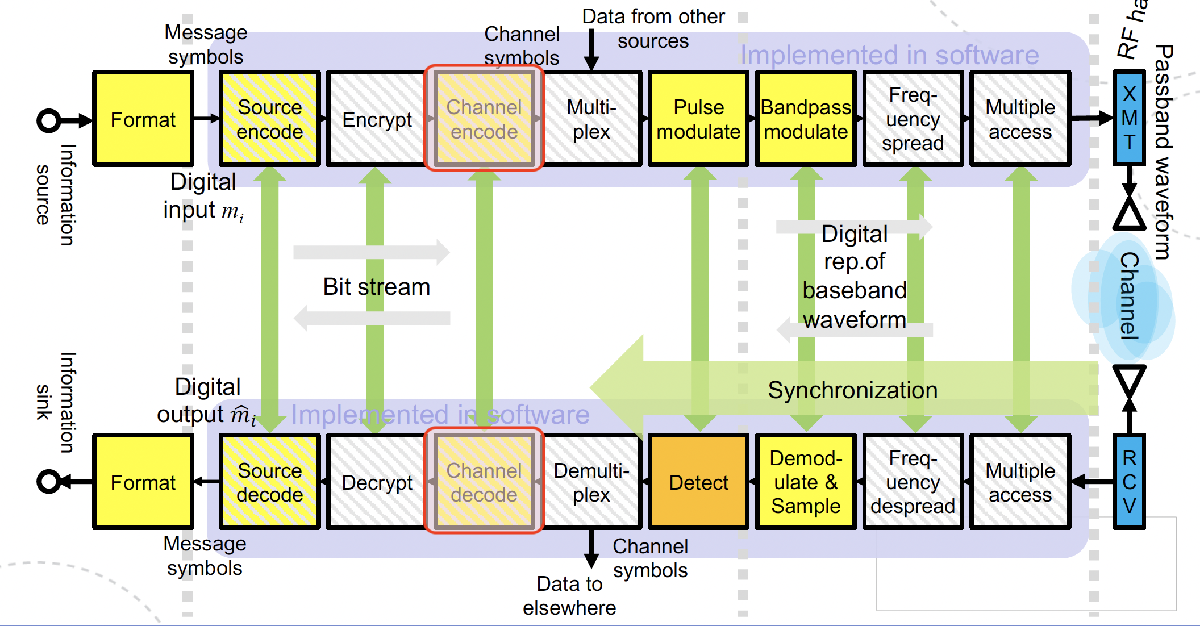

Specifically, the lab session covers the highlighted (red) parts of the schematic depicted above. 

### `Course Content`

- Coding Gain

- Convolutional Codes

- Cyclic redundancy check

- Bit interleaved coded modulation

#### `Task 1 : Hamming Code`

This task illustrates the principle of *block codes*. 

- Generator Matrix

- Parity Check Matrix

- Syndrome

Recomended reading: Section 6.4 *Linear Block Codes *in *Digital Communications, Sklar*

% Tip: Use MatLab inbuilt functions whenever possible 

% Define message length k and codeword length n 
n = 7; k = 4;     
m = n-k;
% Generate random binary message of length k
%x = randi([0 1],k, 1).';
x = [0 1 0 1];
disp(x);

     0     1     0     1




% Generate parity check matrix and generator matrix using hammgen()
[h,g]=hammgen(3);
disp(h);

     1     0     0     1     0     1     1
     0     1     0     1     1     1     0
     0     0     1     0     1     1     1



% Encode the message using encode()
code = encode(x,n,k);
u = mod(code*g.', 2);
%  Use the first column of the codes STANDARD ARRAY to construct the error
%  pattern -> syndrome LUT
E = syndtable(h) % syndrome LUT

E =      0     0     0     0     0     0     0
     0     0     1     0     0     0     0
     0     1     0     0     0     0     0
     0     0     0     0     1     0     0
     1     0     0     0     0     0     0
     0     0     0     0     0     0     1
     0     0     0     1     0     0     0
     0     0     0     0     0     1     0



% Introduce 1-bit errors at different positions in the codeword and calculate the
% syndrome of the error
r=code;

e = [1 0 0 0 0 0 0];
S_e =mod(e*h.',2); %Syndrome
disp(S_e);

     1     0     0



% Flip 1 bit


% Decode using created LUT & check if 1-bit error can be successfully
% decoded

syndrome = mod(E*h.',2);
disp(syndrome);

     0     0     0
     0     0     1
     0     1     0
     0     1     1
     1     0     0
     1     0     1
     1     1     0
     1     1     1



% Creating random bitflip
e_idx = randi(7);
r(e_idx)=mod(r(e_idx)+1,2);

s = mod(r*h.',2);
disp(s);

     1     1     0



[tf, rowIndex] = ismember(s, syndrome, 'rows');

disp(rowIndex);

     7



corrected = mod(r + E(rowIndex, :),2);
disp(code);

     1     1     0     0     1     0     1



disp(corrected);

     1     1     0     0     1     0     1





decoded = decode(corrected, n, k);
disp(decoded);

     0     1     0     1



disp(x);

     0     1     0     1




% ------------------------------------------------- %

% Flip 2 bits at different positions and check if the erraneous codeword
% can be successfully decoded
e_idx2 = randi(7);
while e_idx2 == e_idx
    e_idx2 = randi(7);
end
r(e_idx2)=mod(r(e_idx2)+1,2); % Flipping 1 more bit at a different pos
s2 = mod(r*h.',2);
disp(s2);

     1     0     1



[tf, rowIndex] = ismember(s2, syndrome, 'rows');

disp(tf);

   1



disp(rowIndex);

     6



corrected = mod(r + E(rowIndex, :),2);
disp(code);

     1     1     0     0     1     0     1



disp(corrected);

     1     1     0     1     0     0     0



decoded = decode(corrected, n, k);
disp(decoded);

     1     0     0     0



disp(x);

     0     1     0     1




% Decode with Matlab inbuilt functions and confirm your findings from above


#### `Task 2 : Convolutional Encoder & Decoder`

- Convolutional Encoding

- Convolutional Code Parameters

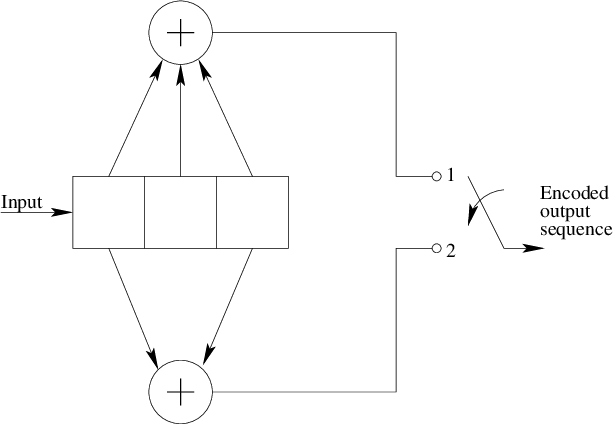

Determine the convolutional coding parameters from the schematic above. Then implement the convolutional encoder for a binary sequence of your choice. 

If you decide to use a non continous message bit stream (i.e., a message of specific length) *flush *the registers. 

*(refer to p. 378ff Digital Communcations, Sklar)*

% Implement the Convolutional Decoder and encode a binary message 


k = 4

% Encode using the built-in convolutional encoder for comparison



#### `Task 3 : Cyclic Redundancy Check - CRC`

Now use a CRC encoder on your message.

Obtain an estimate for the error detection capability of the CRC, i.e. what is the probability of missed error detection of the CRC, and the overhead introduced.

% Original message


% CRC encode


% Convolutional encode (Task 2 function, or matlab built-in function)


% Simulate channel — introduce errors


% Viterbi decode


% CRC check — did Viterbi recover everything correctly?


`Task 4: Interleaving`

Realise a system that utilises convolutional coding and eventually cyclic redundancy checks to correct and detect errors in transmission.

Document the minimum separation achieved by the interleaver.

% Message + CRC


% Convolutional encoding


% Interleaving


% 16-QAM modulation. Note: needs groups of 4 bits, Matlab function qammod()


% Channel — AWGN


% Demodulation


% De-interleaving


% Viterbi decoding


% CRC check


% BER count



Check BER at 10dB, and 5dB

#### `Task 5: Coding Gain`

Compare the BER vs SNR performance of     

- Hamming codes

- Convolutional codes w/ hard-, and soft decoding

This is an unguided exercises. It is recommended to use Matlab inbuilt functions wherever possible. 

% Implementation
